# 課題設定

車の位置$z$、速度$v$を含む状態変数$x$を用意する。車が初期状態$x_0 =\left\lbrack z_{0\;} ,v^{\textrm{ref}} \right\rbrack$から出発し、$\theta \;\left(z\right)$の角度がある中でも速度$v=v^{\textrm{ref}}$で一定になるように入力$u$を与えたい。


$$x=\left\lbrack z\;v\right\rbrack$$



$$\dot{\;x} =f\left(\left\lbrack z,v\right\rbrack \right)=\left\lbrack v,\;u-Mg\;\sin \left(\theta \;\left(z\right)\right)\right\rbrack =\left\lbrack v,u+s\left(z\right)\right\rbrack$$



$$\phi \;\left(\left\lbrack z,v\right\rbrack \right)=\frac{1}{2}{\left(v-v^{\mathrm{ref}} \right)}^2$$



$$L=\;\frac{1}{2}{\left(v-v^{\mathrm{ref}} \right)}^2 +\frac{1}{2}u^2$$



$$H=L+\lambda^T f=\left\lbrace \frac{1}{2}{\left(v-v^{\mathrm{ref}} \right)}^2 +\frac{1}{2}u^2 \right\rbrace +\left\lbrace \lambda {\;}_{1\;} v+\lambda {\;}_2 \left(u+s\left(z\right)\right)\right\rbrace$$



$$\phi {\;}_x =\left\lbrack 0\;,\left(v-v^{\textrm{ref}} \right)\right\rbrack$$



$$H_u =\lambda {\;}_{2\;} +2u$$



$$H_x =\left\lbrack 0,\left(v-v^{\textrm{ref}} \right)+\lambda {\;}_1 \right\rbrack$$


## 傾斜について

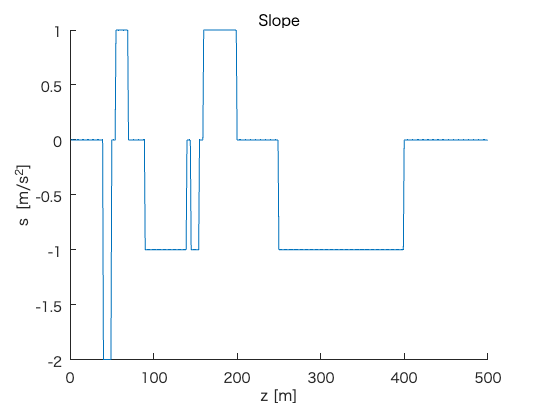

slopedata = Slopedata;

z_s = 1:500;
s_s = zeros(size(z_s));

for k=1:length(z_s)
    s_s(k) = slopedata.s(z_s(k));
end

figure
hold on
title("Slope")
plot(z_s,s_s)
xlabel("z [m]")
ylabel("s [m/s^2]")
hold off

## ルールの設定

vref = 10;
z0 = 0;
x0 = [z0 vref];

delta_t = 0.5;
t_final = 50;
max_k = t_final/delta_t;
t_s = (1:max_k)*delta_t;

## 降下法

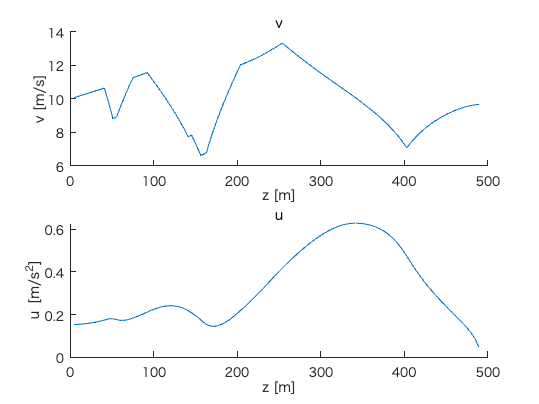

gdo = GdOptimizer(x0,delta_t,max_k,vref);
gdo_s = [gdo];
for epoch = 1:20
    gdo = gdo.epoch;
    gdo_s = [gdo_s gdo];
end

final_gdo = gdo_s(length(gdo_s));
gdo_x_s = final_gdo.x_s;
gdo_u_s = final_gdo.u_s;

figure
subplot(2,1,1)
hold on
title("v")
plot(gdo_x_s(:,1),gdo_x_s(:,2))
xlabel("z [m]")
ylabel("v [m/s]")
hold off

subplot(2,1,2)
hold on
title("u")
plot(gdo_x_s(:,1),gdo_u_s)
xlabel("z [m]")
ylabel("u [m/s^2]")
hold off

## fminunc

slopedata = Slopedata;
objective = @(u_s) get_J_from_u(u_s,slopedata,delta_t,x0,vref);
u_s = zeros([1, max_k]);
[fmiinunc_u_s,fval] = fminunc( ...
    objective, u_s,optimoptions("fmincon","MaxIterations",400));


ソルバーが途中で停止しました。

fminunc は関数評価の制限、options.MaxFunctionEvaluations = 3.000000e+03 
を超過したため、停止しました。



## それぞれの入力に対して車の動きをシミュレート

gdo_final_u_s = gdo_s(length(gdo_s)).u_s;
gdo_final_x_s = car_steps(x0,gdo_final_u_s,delta_t,slopedata);
fminunc_x_s = car_steps(x0,fmiinunc_u_s,delta_t,slopedata);
free_u_s = zeros(size(t_s));
free_x_s = car_steps(x0,free_u_s,delta_t,slopedata);

## 結果

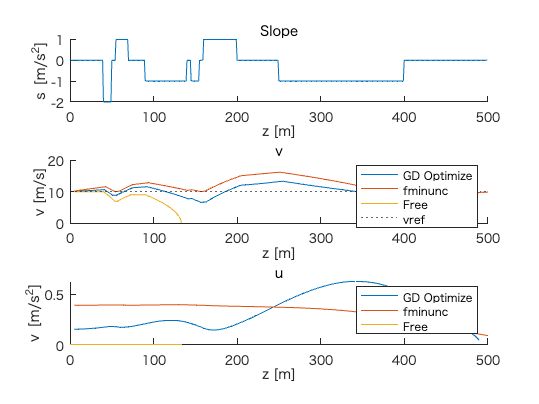

figure
xlim_setting = [0 500];

subplot(3,1,1)
hold on
title("Slope")
plot(z_s,s_s)
xlabel("z [m]")
ylabel("s [m/s^2]")
xlim(xlim_setting)
hold off

subplot(3,1,2)
hold on
title("v")
plot(gdo_final_x_s(:,1),gdo_final_x_s(:,2))
plot(fminunc_x_s(:,1),fminunc_x_s(:,2))
plot(free_x_s(:,1),free_x_s(:,2))
xlabel("z [m]")
ylabel("v [m/s]")
yline(vref,":")
legend("GD Optimize","fminunc","Free","vref")
xlim(xlim_setting)
ylim([0 20])
hold off

subplot(3,1,3)
hold on
title("u")
plot(gdo_final_x_s(:,1),gdo_final_u_s)
plot(fminunc_x_s(:,1),fmiinunc_u_s)
plot(free_x_s(:,1),free_u_s)
xlabel("z [m]")
ylabel("v [m/s^2]")
legend("GD Optimize","fminunc","Free")
xlim(xlim_setting)
hold off